x0 = zeros(4,1); %Mean of initial state
P0 = diag([100 100 1 1]);%Covariance matrix of initial state
Phi = [eye(2) eye(2);zeros(2,2) eye(2)];% State transition matrix
Q = [1/3*eye(2),1/2*eye(2);1/2*eye(2),eye(2)]; % Covariance matrix of state model
n = 40; % length of track
dim = 2+2;% Dimension 2D position and 2D velocity
X=nan(dim,n+1); %Track t=0...t=n
X(:,1)=x0;
for t=1:n
    X(:,t+1)=Phi*X(:,t)+mvnrnd(zeros(1,4),Q)';
end
figure;
plot(X(1,:),X(2,:),'b.-');
hold on
xlabel('x coordinate')
ylabel('y coordinate')
axis equal
title('Track')
% Generate measurement you can use
% y(:,i)=H*x(:,i)+mvnrnd(zeros(1,2),R)';

lisätään toi generoitu "mittausdata"

% Generate measurement you can use
H = [eye(2) zeros(2,2)];
sigmax2 = 4^2;
sigmay2 = 2^2;
R = diag([sigmax2,sigmay2]);
Y = nan(2,n);
for t=1:n
    Y(:,t)=H*X(:,t+1)+mvnrnd(zeros(1,2),R)';
end
plot(Y(1,:),Y(2,:),'r.-')
title('Track and measurements')

lisätään Kalman Filter-arvot

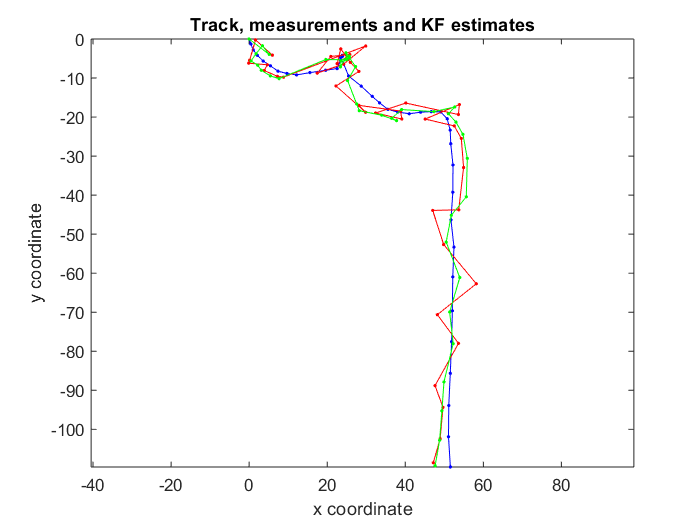

Estimate = nan(size(X));
Estimate(:,1)=x0;
P = nan(dim,dim,n+1);
P(:,:,1) = P0;
for t=1:n
 Estimate(:,t+1) = Phi*Estimate(:,t); % Prior estimate
 P(:,:,t+1) = Phi*P(:,:,t)*Phi'+Q; % Prior covariance
 K = P(:,:,t+1)*H'/(H*P(:,:,t+1)*H'+R); % Kalman gain
 Estimate(:,t+1) = Estimate(:,t+1)+K*(Y(:,t)-H*Estimate(:,t+1));% Posterior estimate
 P(:,:,t+1) = (eye(dim)-K*H)*P(:,:,t+1);% Posterior covariance
end
plot(Estimate(1,:),Estimate(2,:),'g.-')
title('Track, measurements and KF estimates')